# 2021 September 26 - ADSP 2021/2022

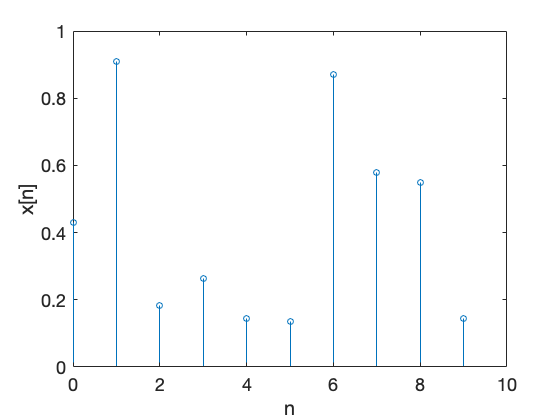


clear;  close all; clc;

% Define the sequence x[n]:
N = 10;
xn = rand(N,1);     % sequence generated as random numbers from a uniform [0,1] distribution
n = 0:1:N-1;        % discrete time index

% Plot the generated sequence:
figure;
stem(n,xn);
xlabel('n'), ylabel('x[n]')
set(gca, 'FontSize', 18)

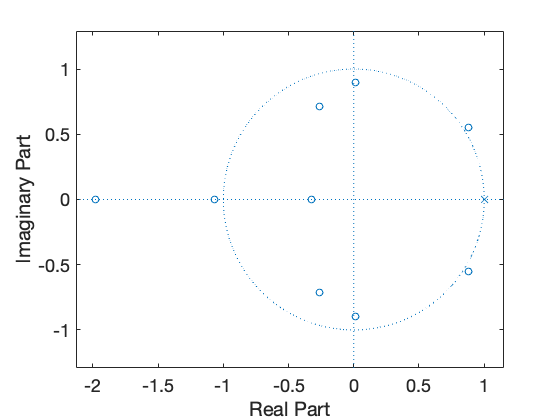

% Compute the roots of the polinomial:
zk = roots(fliplr(xn));

% Plot the roots of the Z-T on the complex plane:
figure;
zplane(zk,1)
set(gca, 'FontSize', 18)

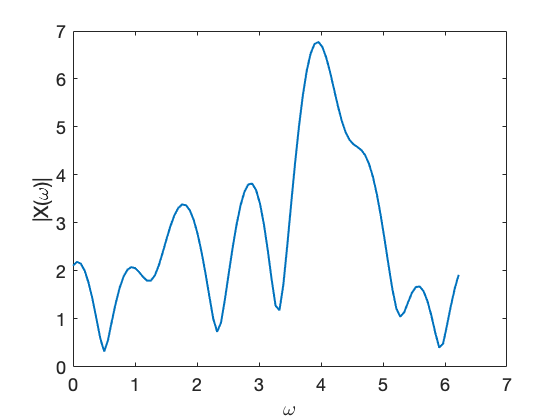

% Compute the F.T. from Z-T:
Nk = 100;
[X, w] = freqz(zk, 1, Nk, 'whole');

% plot the frequency response:
figure;
plot(w, abs(X), 'LineWidth', 2);
xlabel('\omega'), ylabel('|X(\omega)|')
set(gca, 'FontSize', 18)

## Convolution:

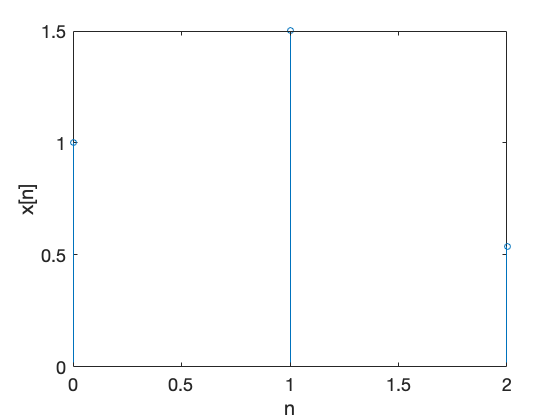

xn = [1, 0.9];
hn = [1, 0.6];

yn = conv(xn, hn);
L = length(xn) + length(hn) - 1;    % length of the output sequence
n = 0:1:L-1;
figure;
stem(n, yn)
xlabel('n'), ylabel('x[n]')
set(gca, 'FontSize', 18)

## Causal exponential case:

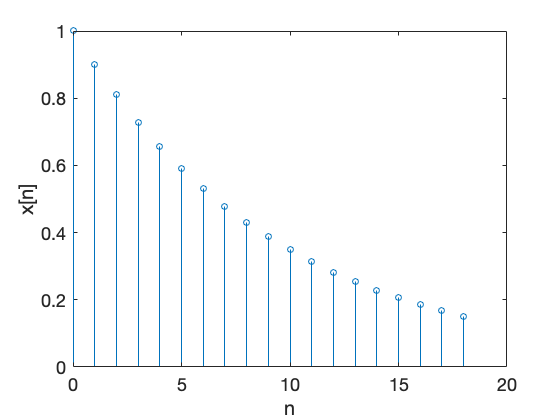

N = 19;
a = 0.9;
n = 0:1:N-1;
xn = a.^n;

% plot the xn sequence:
figure;
stem(n,xn)
xlabel('n'), ylabel('x[n]')
set(gca, 'FontSize', 18)

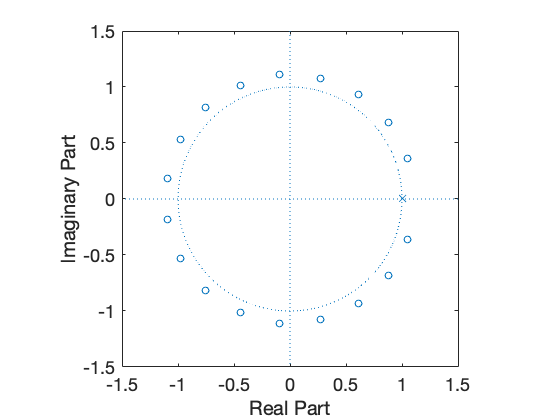

% Let's compute the roots of xn:
% recal that roots(C) computes the roots of the polynomial whose coefficients
% are the elements of the vector C. If C has N+1 components, the polynomial is 
% C(1)*X^N + ... + C(N)*X + C(N+1). Therefore, we use fliplr(xn) to invert
% the input sequence and to meet the roots expected input:
zk = roots(fliplr(xn));
pk = 1;                     % No poles
Bz = xn;                    % The numerator of the ZT
Az = 1;                     % The denumerator of the ZT

% Plot the roots of the Z-T on the complex plane:
figure;
zplane(zk,pk)
set(gca, 'FontSize', 18); xlim([-1.5 1.5]); ylim([-1.5 1.5])

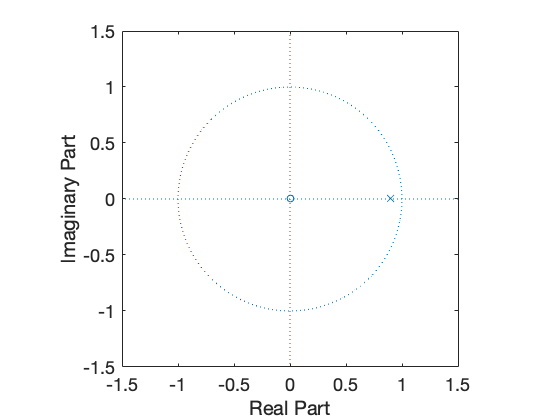

% Since we know that the Z-T of the causal exponential, that is
% 1/(1-az^-1):
Bz_true = 1;         % No zeros
Az_true = [1 -a];    % 1 pole.

% diagram of true Z-T:
figure;
zplane(Bz_true, Az_true, 'r');
set(gca, 'FontSize', 18); xlim([-1.5 1.5]); ylim([-1.5 1.5])

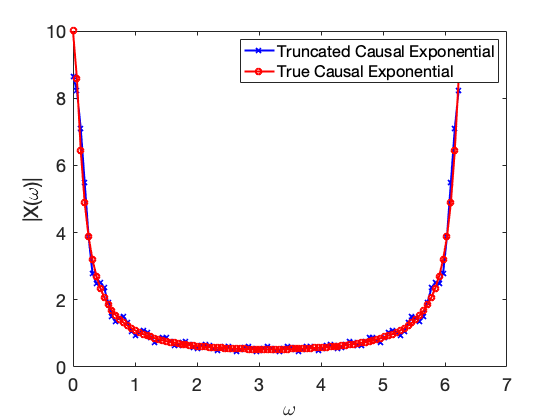

% Compute the F.T. from Z-T:
Nk = 100;
[X, w] = freqz(Bz, Az, 'whole', Nk);

% Since we know that the Z-T of the causal exponential, let's compute the
% true frequency response
[X_true, w_true] = freqz(Bz_true, Az_true, 'whole', Nk);

% plot the frequency response:
figure;
plot(w, abs(X), '-bx', "LineWidth",2);
hold on;
plot(w_true, abs(X_true), '-ro', "LineWidth",2);
xlabel('\omega'), ylabel('|X(\omega)|')
legend('Truncated Causal Exponential', 'True Causal Exponential')
set(gca, 'FontSize', 18)